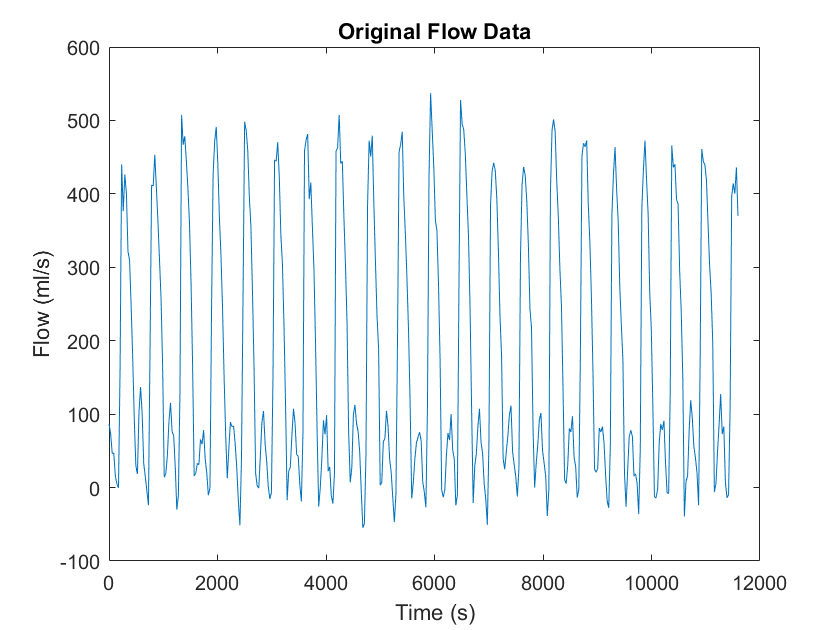

 % Heart function analysis
% This program analyzes the effect of exercise on the function of the heart.
% It reads flow data from an MRI of blood flow out of patients’ left ventricle (LV).
% The data is analyzed to learn about how diseased hearts respond to the increased
% load experienced during exercise.

% Clear workspace, command window and close all figures
clear; 
clc; 
close all;

% Load data from flow.csv
data = csvread('flow.csv');

% Store data in separate variables
times = data(:, 1);
flow = data(:, 2);

% Plot the flow measurements vs. times
figure(1);
plot(times, flow);
title('Original Flow Data');
xlabel('Time (s)');
ylabel('Flow (ml/s)');

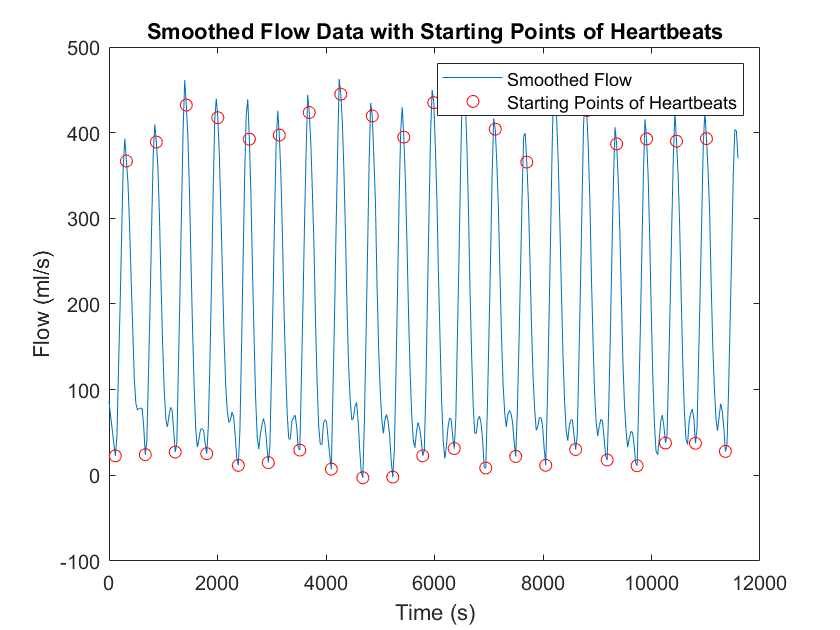


% Smooth the plot to reduce the noise
flow_smoothed = smooth(flow);

% Find peaks and troughs in the data
threshold = 300;
peaks = find(flow_smoothed > threshold & ...
             flow_smoothed > circshift(flow_smoothed, -1) & ...
             circshift(flow_smoothed, -1) > circshift(flow_smoothed, -2) & ...
             circshift(flow_smoothed, 1) > circshift(flow_smoothed, 2));

troughs = zeros(length(peaks)-1, 1);

for i = 1:length(peaks)-1
    % Search backwards in time from the peak to find the trough
    j = peaks(i);
    while j > 1 && flow_smoothed(j) > flow_smoothed(j-1)
        j = j - 1;
    end
    troughs(i) = j;
end

% Ignore the last heartbeat as it may be incomplete
peaks = peaks(1:end-1);

% Divide up the flow data into separate cardiac cycles using the troughs
heartbeats = cell(length(troughs), 1);
for i = 1:length(troughs)-1
    heartbeats{i} = flow_smoothed(troughs(i):peaks(i+1));
end

% Plot the smoothed flow data with the locations of the starting points of the heartbeats
figure(2);
plot(times, flow_smoothed);
hold on;
plot(times(troughs), flow_smoothed(troughs), 'ro');
title('Smoothed Flow Data with Starting Points of Heartbeats');
xlabel('Time (s)');
ylabel('Flow (ml/s)');
legend('Smoothed Flow', 'Starting Points of Heartbeats');

hold off

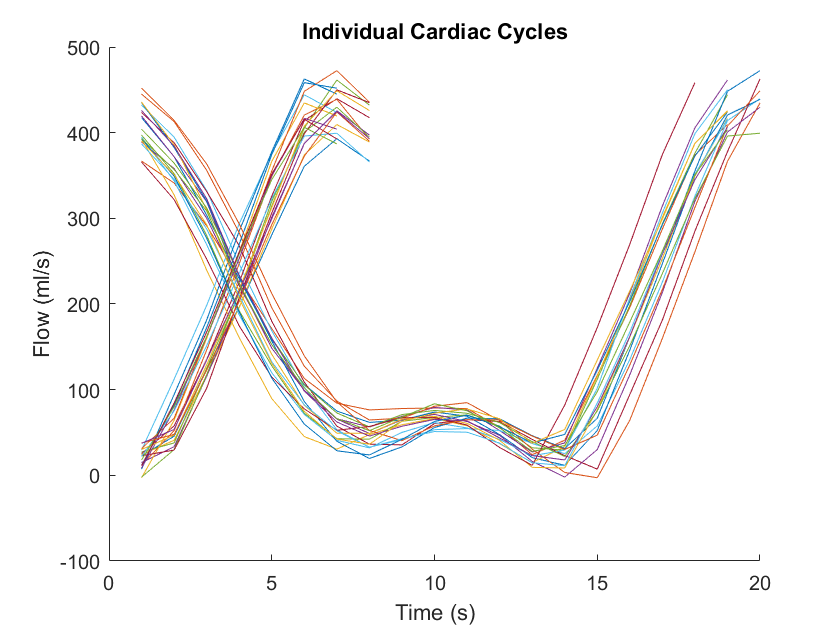


% Plot the data for all the individual cardiac cycles on the same graph
figure(3);
hold on;
for i = 1:length(heartbeats)
    plot(heartbeats{i});
end
title('Individual Cardiac Cycles');
xlabel('Time (s)');
ylabel('Flow (ml/s)');

hold off

% Compute the area under the flow data points for each heartbeat
areas = zeros(length(heartbeats), 1);
for i = 1:length(heartbeats)
    areas(i) = trapz(heartbeats{i});
end

% Compute the mean and standard deviation of the areas of all heartbeats
mean_area = mean(areas);
std_area = std(areas);

% Display the mean and standard deviation of the areas of all heartbeats
fprintf('Mean Area: %.2f\n', mean_area);

Mean Area: 2264.79


fprintf('Standard Deviation of Areas: %.2f\n', std_area);

Standard Deviation of Areas: 764.92


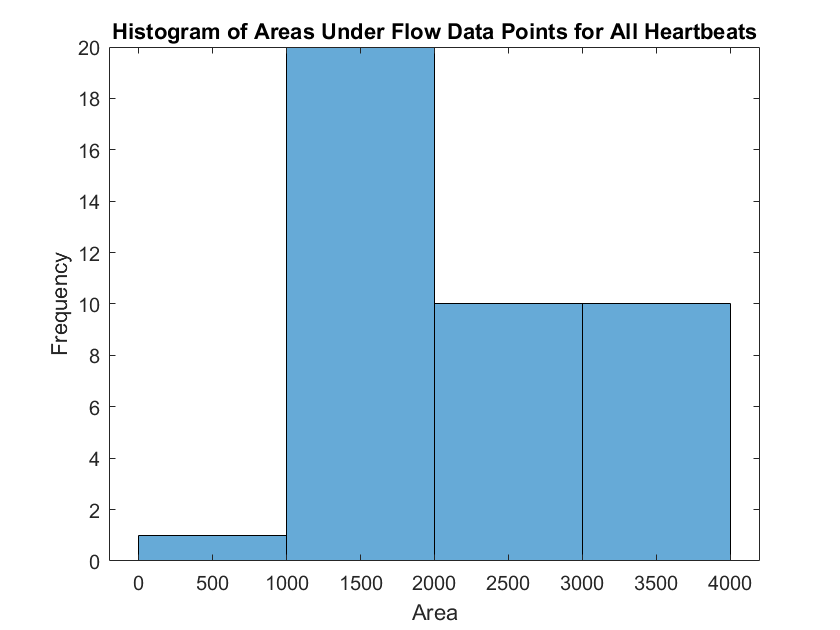


% Plot a histogram of the areas under the flow data points for all heartbeats
figure(4);
histogram(areas);
title('Histogram of Areas Under Flow Data Points for All Heartbeats');
xlabel('Area');
ylabel('Frequency');